# Using SVD to Compress Images

The goal is to compress an image. There are two basic types of compression, one is called lossless and the other is lossy. 

**Lossless: **

The image, which consists of a stream of bits can be fully recovered from the compressed image. Typically, lossless image processing involves removing non-essential bits (i.e. for a text, removing spaces, etc). Examples: zip, tar, gunzip, compress

**Lossy: **

The image is irreversibly changed by stripping bits that do not contribute greatly to the content of the image. In other words, the image "looks" like the original image, the degradation is insignificant and the loss of size is significant. 

clear, close all
%nasacolor=imread('TarantulaNebula.jpg');
MonaLisacolor=imread('Mona_Lisa.jpg');

Check size of file:

size(MonaLisacolor)

ans =         4289        2835           3


ls -l Mona_Lisa.jpg   3.34MB

*This image appears in the Wikipedia entry on the famous painting.*

The variable MonaLisacolor will be a  matrix of integer values between 0 and 255.

Display the color plot using the command

image(MonaLisacolor); axis equal


The third subscript of the array nasa refers to the red, green, and blue color components. To simplify this exercise, turn it into a greyscale with ordinary double precision values 0-255 using the following commands. 

**Remark: **This is a cheap but dirty way to create a grayscale image from an rgb image. It is good enough for our purpose here:

Mona=sum(MonaLisacolor,3,'double');  %sum up red+green+blue
m=max(max(Mona));                %find the max value
Mona=Mona*255/m;                 %make this be bright white

The result from these commands is that nasa is an ordinary   array of double precision numbers. 

size(Mona)

ans =         4289        2835


Matlab has the notion of a ``colormap'' that determines how the values in the matrix will be colored. Use the command

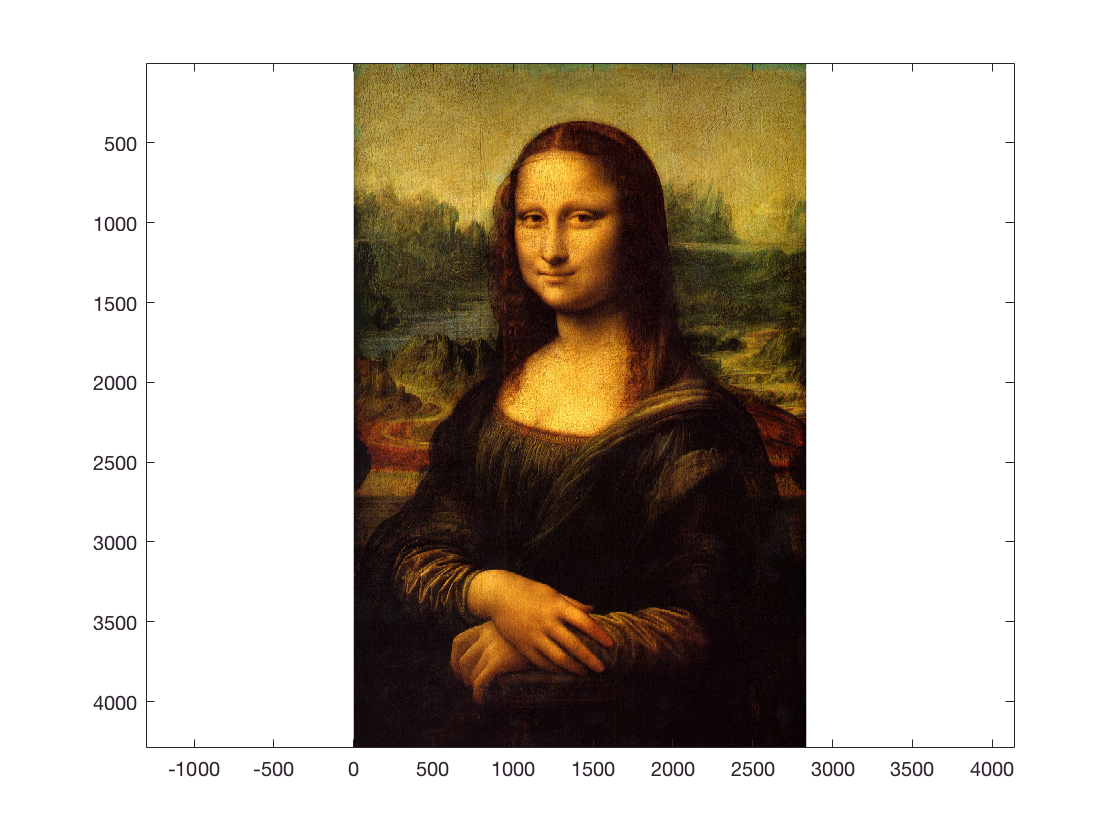

colormap(gray(256));

to set a grayscale colormap. Now you can show the picture with the command

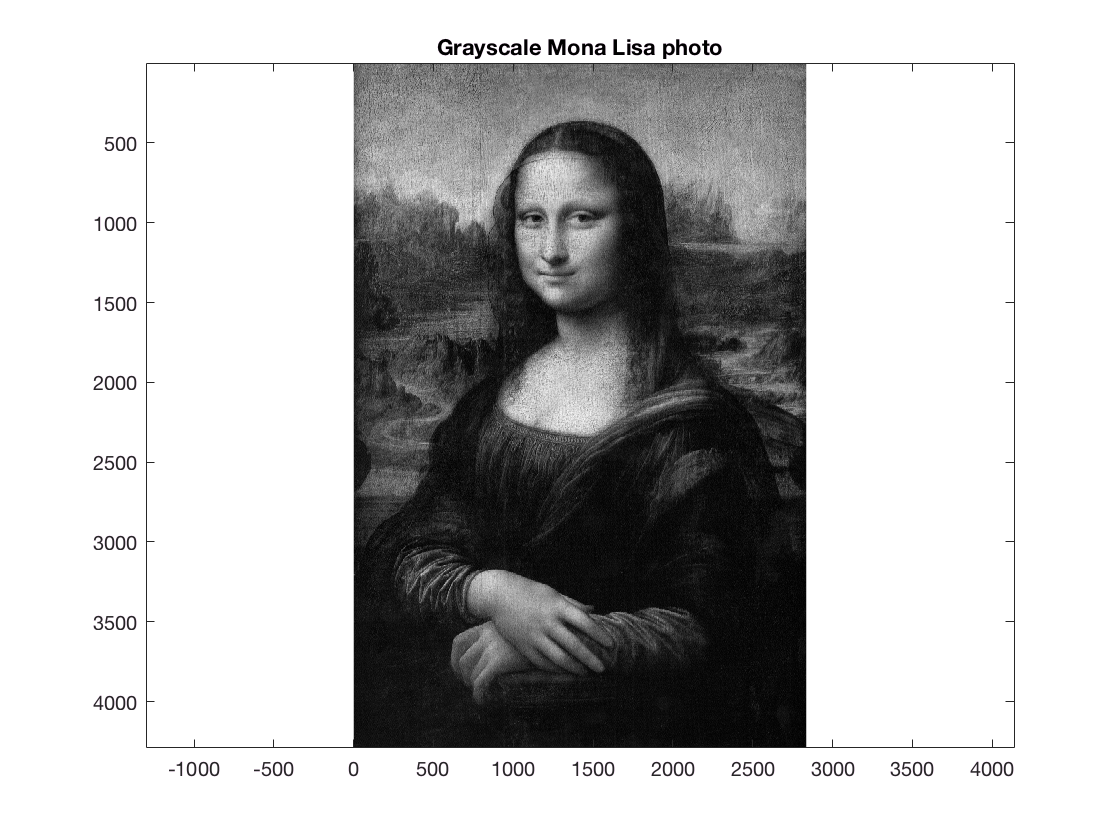

figure(1)
image(Mona), axis equal
title('Grayscale Mona Lisa photo');

Use the command

[U S V]=svd(Mona); 

to perform the singular value decomposition. 

Plot the singular values on a semilog scale: 

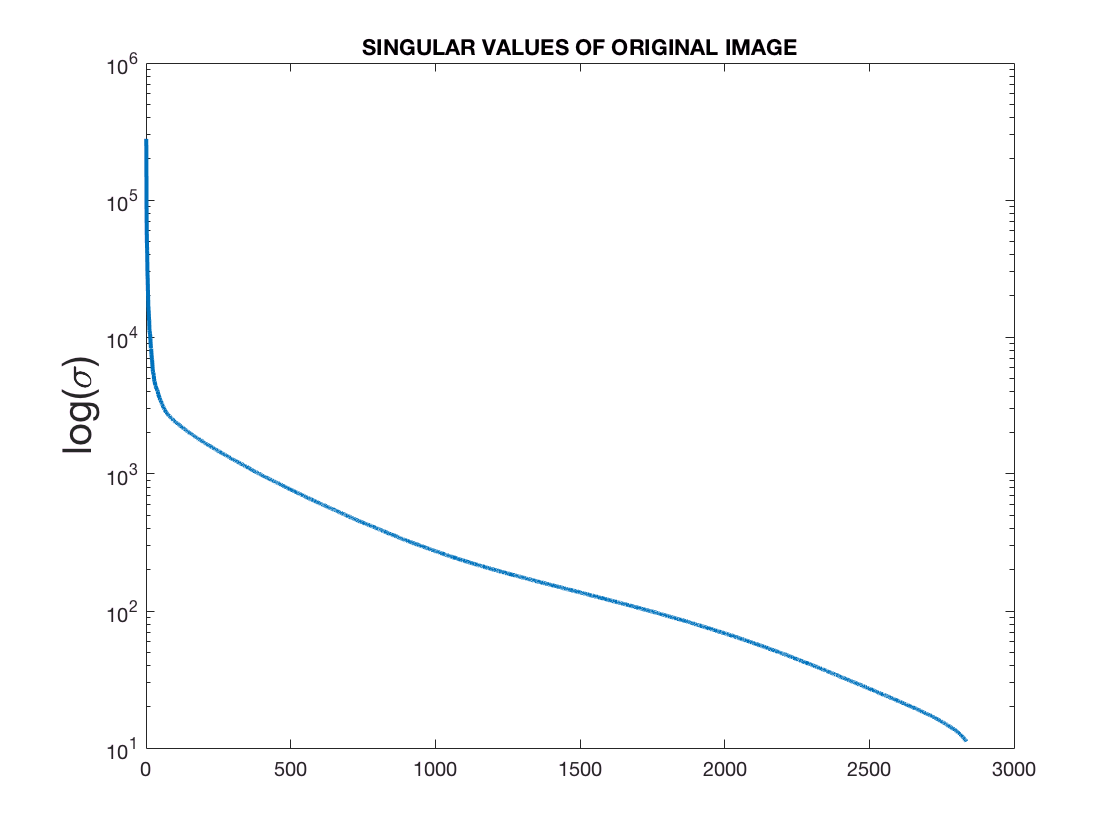

figure(2) 
semilogy(diag(S),'linewidth',2); title('SINGULAR VALUES OF ORIGINAL IMAGE'); ylabel('log(\sigma)','fontsize',20)

We note that the singular there is a sharp transition in the singular values, at around 100 or so. These first 100 degrees of freedom carry most of the information in the figure, so cutting out more than about 100 will lead to significant degradation in the figure.

Construct the three new matrices

Mona500=U(:,1:500)*S(1:500,1:500)*V(:,1:500)';
Mona200=U(:,1:200)*S(1:200,1:200)*V(:,1:200)';
Mona100=U(:,1:100)*S(1:100,1:100)*V(:,1:100)';

**These matrices are of lower rank than the Mona matrix, and can be stored in a more efficient manner.**

 The Mona matrix is  

size(Mona)

ans =         4289        2835


4289 X 2835

and requires storing

12,159,315

single  precision  numbers.

 In contrast, Mona100 requires subsets of U and V that are  

4289X100

 and the diagonal of S, for a total of 

2X(4289X100) + 100 =857,900 .  

This is 7% of the original storage requirement.

Plots of the three matrices Mona500, Mona200 and Mona100 as images:

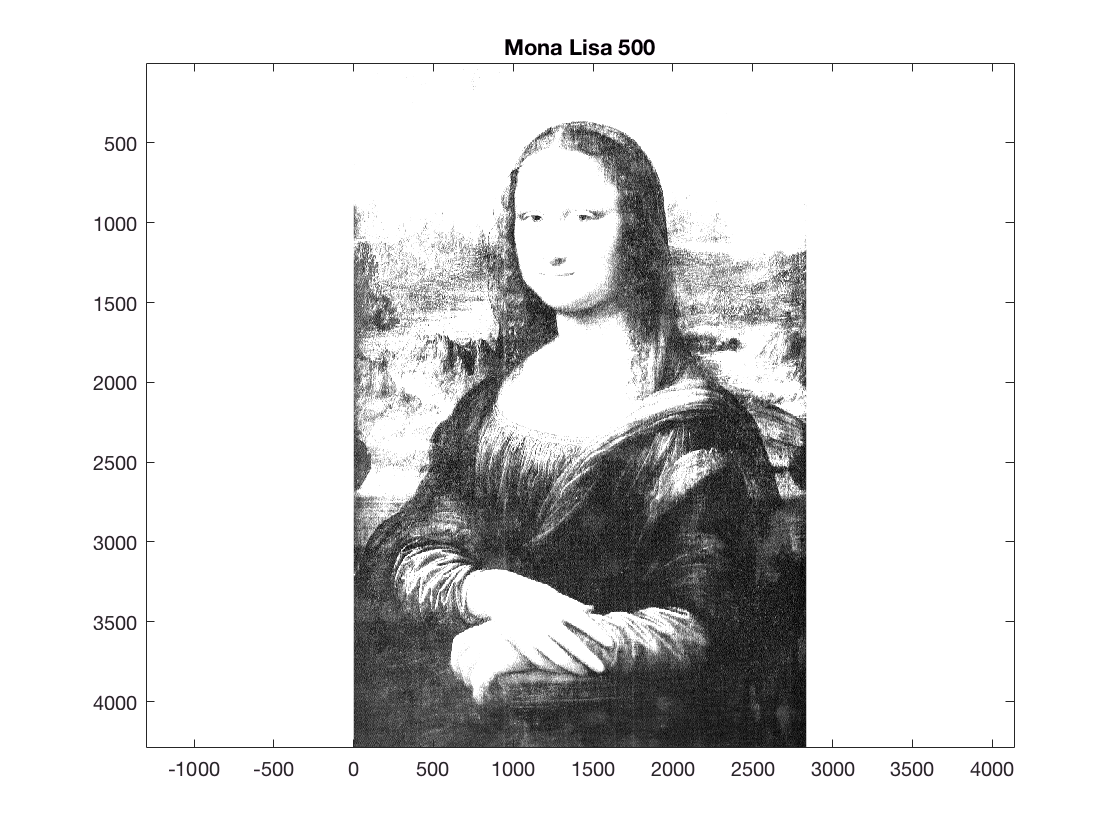

figure(10)
colormap('gray')
image(Mona500),  axis equal
title('Mona Lisa 500')

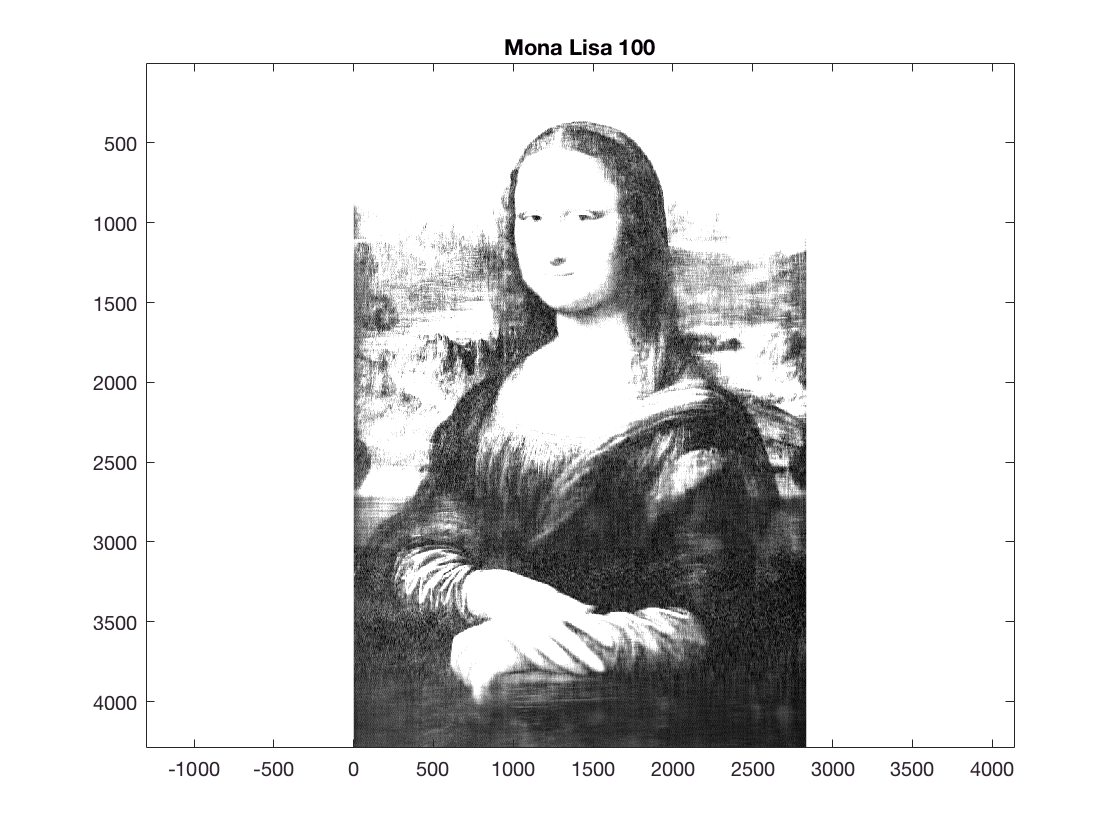


figure(20)
image(Mona200),  axis equal
colormap('gray')
title('Mona Lisa 200')

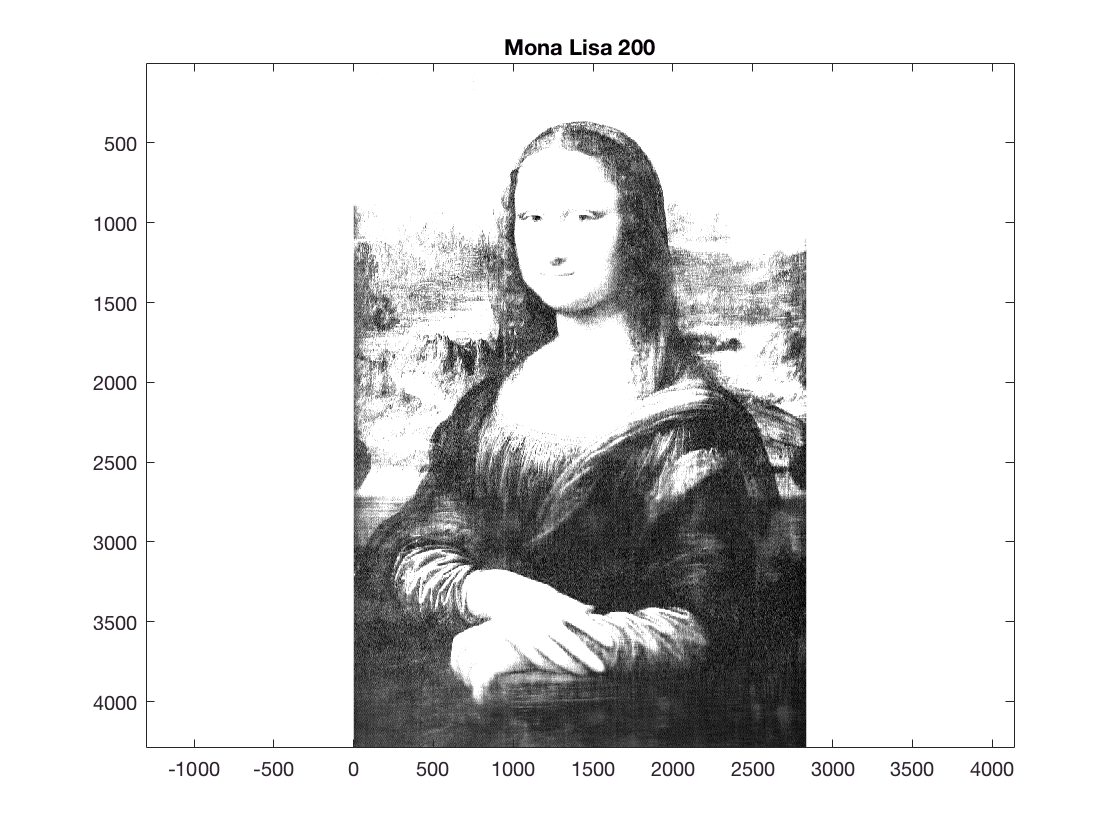


figure(30)
colormap('gray')
image(Mona100),  axis equal
title('Mona Lisa 100')

The size of the S matrix, in terms of its rank:

rank(Mona)

ans = 2835

You should only very slight differences between the original and the one with 500 singular values, some  differences with 200 singular values while you should see significant degradation of the image in the case of 100 singular values. 